# Week 1 Exercise Set

### Kushnava Singha - 2872230

1.  

A.

abs(x) Absolute value of a real number; 10magnitude of complex number

acos(x) Arccosine with result in radians

acosh(x) Inverse hyperbolic cosine

angle(x) Phase angle of complex number (in radians)

asin(x) Arcsine with result in radians

asinh(x) Inverse hyperbolic sine

atan(x) Arctangent with result in radians

atan2(x,y) Four quadrant arctangent with result in radians

atanh(x) Inverse hyperbolic tangent

ceil(x) Round toward plus infinity

conj(x) Complex conjugate

cos(x) Cosine with x in radians

cosh(x) Hyperbolic cosine

exp(x) Exponential of x

fix(x) Round toward zero

floor(x) Round toward minus infinite

gcd(x,y) Greatest common divisor of integer x and y

imag(x) Imaginary part of complex number x (i.e. imag(x+iy) = y)

lcm(x,y) Least common multiple of integers x and y

log(x) Natural logarithm of x, i.e.: ln(x) = e log(x)

log10(x) Base-10 logarithm of x, i.e.: 10 log(x)

mod(x,y) x modulo y (i.e. mod(5,2) = 1)

prod(x) Product of elements

real(x) Real part of complex number x (i.e. real(x+iy) = x)

rem(x,y) Remainder after division of x/y (i.e. rem(5,3)=2)

round(x) Round toward nearest integer

sign(x) Signum-function (i.e.: -1 for x<0, 0 for x=0 and 1 for x>0)

sin(x) Sine with x in radians

sinh(x) Hyperbolic sine

sqrt(x) Square root

sum(x) Sum of elements

tan(x) Tangent

tanh(x) Hyperbolic tangent

B.

Syntaxes for 

    Cosine : y = cos(x)

    Natural Logarithm : y = log(x)

    Square Root : y = sqrt(x)

2. 

Hungry = true;
Cookies = 0;
while Hungry == true
    Cookies = Cookies + 1;
    quest = "Still Hungry ?"
    Hungry = questdlg(quest,'Question','Yes','No','Yes');
    switch Hungry
        case 'Yes' 
            Hungry = true;
        case 'No'
            Hungry = false;
    end
end

quest = "Still Hungry ?"

quest = "Still Hungry ?"

quest = "Still Hungry ?"

quest = "Still Hungry ?"

disp('')
disp(['Not hungry anymore after:', num2str(Cookies),' cookies.'])

Not hungry anymore after:4 cookies.


3.

function area = calcarea(R)
    area = 4*pi*R^2; 
end

function vol = calcvol(R)
    vol = (4/3)*pi*R^3;
end
R = input('What is the radius of the Sphere ?')

R = 10

area = calcarea(R);
vol = calcvol(R);
fprintf('Sphere with radius of %0.1f units has a volume of %0.2f unit cubed and a surface area of %0.2f unit squared.',R,vol,area)

Sphere with radius of 10.0 units has a volume of 4188.79 unit cubed and a surface area of 1256.64 unit squared.

4.

function [x,y]=convert_rectangular(r, phi)
    x = r*cos(phi);
    y = r*sin(phi);
end
prompt ={'Enter the value of R : ', 'Enter the value of Phi : '};
polar = inputdlg(prompt,"Input");
r = str2double(polar{1});
phi = str2double(polar{2});
[x,y]=convert_rectangular(r, phi);
fprintf('The equivalent rectangular coordinates for the polar coordinates (%0.1f units, %0.1f radians) are (%0.2f units, %0.2f units).\n',r, phi,x,y)

The equivalent rectangular coordinates for the polar coordinates (10.0 units, 45.0 radians) are (5.25 units, 8.51 units).


5.

N=10;
v = zeros(1,N);
v = changem(v,N);
M = diag(v);
%Change the Main Diagonal 
for i = 2:N
    v = zeros(1,N-i+1);
    v = changem(v,N-i+1);
    d1 = diag(v,i-1);%Changing Superdiagonal 
    d2 = diag(-v, -(i-1));%Changing Subdiagonal
    M = M + d1+d2;
end
disp(M)

    10     9     8     7     6     5     4     3     2     1
    -9    10     9     8     7     6     5     4     3     2
    -8    -9    10     9     8     7     6     5     4     3
    -7    -8    -9    10     9     8     7     6     5     4
    -6    -7    -8    -9    10     9     8     7     6     5
    -5    -6    -7    -8    -9    10     9     8     7     6
    -4    -5    -6    -7    -8    -9    10     9     8     7
    -3    -4    -5    -6    -7    -8    -9    10     9     8
    -2    -3    -4    -5    -6    -7    -8    -9    10     9
    -1    -2    -3    -4    -5    -6    -7    -8    -9    10



6.

N = input('Enter an Aribtrary uneven Natural Number Larger than 3 : ');
x = zeros(1, N)

x =      0     0     0     0     0     0     0


for i = 1:N
    x(1,i) = i;
end
x =x*10

x =     10    20    30    40    50    60    70


x1 = x

x1 =     10    20    30    40    50    60    70


x1(2) = [];
x1(end) = [];
disp(x1)

    10    30    40    50    60



x2 = x;
x2(ceil(N/2))=[]

x2 =     10    20    30    50    60    70


x3 = zeros(1,ceil(N/2));
count = 1;
for i = 1:N
    if mod(i,2) ~=0
        x3(1,count)= x(1,i);
        count = count +1;
    end
end
disp(x3)

    10    30    50    70



x4 = zeros(1,N);
count =0;
for i = 1:N
    if mod(x(1,i),2) ~=0
        count = count +1;       
        x4(1,count)= x(1,i);
    end
end
x4 = x4(1:count)


x4 =

  1×0 empty double row vector



x5 = fliplr(x(1:N))

x5 =     70    60    50    40    30    20    10


x6 = zeros(1, N);
for i = 1:N
    if x(1,i)>=mean(x)
        count = count+1;
        x6(1,count) = x(1,i);
    end
end
x6 = x6(1:count)

x6 =     40    50    60    70


7.

A = [1,2;3,4];
B = ones(size(A));
c = [10, 20]';
disp(A*B);% Matrix Multiplication

     3     3
     7     7



disp(A.*B);% Individual element in A is multiplies by the element in the same position in matrix B

     1     2
     3     4



disp(A./B);% Individual element in A gets divided by the element in the same position in matrix B

     1     2
     3     4



disp(A.^B);% Individual element in A is raisded to power of the element in the same position in matrix B

     1     2
     3     4



disp(A*c);% Matrix multiplication operation

    50
   110



disp(c'*A);% c is Transposed and matrix multiplied with A

    70   100



8.

function f = f(x)
    f = x^2*cos(x);
end
function g = g(x)
    g = x^2*sin(x);
end
x = linspace(-pi,pi);
disp(size(x,2))

   100



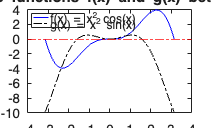

y_sin = zeros(1,size(x,2));
y_cos = zeros(1, size(x, 2));
for i = 1: size(x,2)
    y_sin(1,i)= f(x(i));
    y_cos(1,i) = g(x(i));
end
p1 = plot(x, y_cos, 'b'); hold on     
p2 = plot(x, y_sin, '-.k');       
p3 = yline(0, '-.r');                 

legend([p1 p2],'f(x) = x^2 cos(x)','g(x) = x^2 sin(x)','Location', 'northwest');

title('2D plot of the functions f(x) and g(x) between -\pi abd \pi')
xlabel('-\pi < x < \pi')

9.

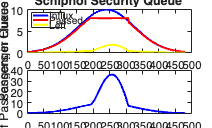

deltat =1;
t=0:deltat:60*8;

pmax = 10;
tmax= 4*60;
spread = 120;
p =pmax*exp(-((tmax-t)/spread).^2);

qmax=8;
kr=0.05;
N0=0;
N=zeros(length(t),1); q=zeros(length(t),1); r=zeros(length(t),1);
N(1)=N0;
for it=2:length(t)
    q(it)=min(N(it-1)/deltat,qmax);
    r(it)=kr*N(it-1);
    N(it)= N(it-1)+(p(it)-q(it)-r(it))*deltat;
end
figure;
subplot(2,1,1)
plot(t, p, 'b', 'LineWidth', 1.5); hold on;
plot(t, q, 'r', 'LineWidth', 1.5);
plot(t, r, 'y', 'LineWidth', 1.5);

xlabel('Time [min]');
ylabel('Passenger Fluxes [n/min]');
title('Schiphol Security Queue ');
legend('Influx', 'Passed', 'Left','Location', 'northwest');

subplot(2,1,2)
plot(t,N,'b','LineWidth',1.5);
xlabel('Time[min]');
ylabel('Number of Passengers in Queue');